### Plotting Fig.S3: Time-scale comparision between the dipolar Hamiltonian and the Floquet Hamiltonian

Code last modified  by Yuchen Li, 2023-10-12

clear;clc

S.mat: the first line is the observable value for Floquet driving, and the second line is the one for free evolution

S_uncert.mat: the errorbar of S, extracted from the FID

load S.mat
load S_uncert.mat

figure()
J=2*pi*1460; %average value of J, see Fig.S1
tau=5*1e-6; %in us, average pulse interval of the rf sequence

quench_time_seq1=24*tau*(0:40); %one period of Floquet driving is 24*tau. There are 0:40 cycles
quench_time_seq2=12*1e-6*(0:40);%

x1=quench_time_seq1*J;
x2=quench_time_seq2*J;

y1=S(1,:);
y2=S(2,:);
y1_uncert=FID_uncertainty(1,:);
y2_uncert=FID_uncertainty(2,:);

sqrt(mean((y1-y2).^2))

ans = 0.0046

max(abs(y1-y2))

ans = 0.0080

abs(y1-y2)

ans =          0    0.0006    0.0034    0.0043    0.0068    0.0071    0.0080    0.0076    0.0072    0.0061    0.0057    0.0058    0.0062    0.0064    0.0071    0.0069    0.0058    0.0062    0.0047    0.0038    0.0033    0.0027    0.0037    0.0030    0.0032    0.0029    0.0033    0.0036    0.0029    0.0030    0.0029    0.0032    0.0031    0.0032    0.0029    0.0032    0.0027    0.0035    0.0027    0.0024    0.0019


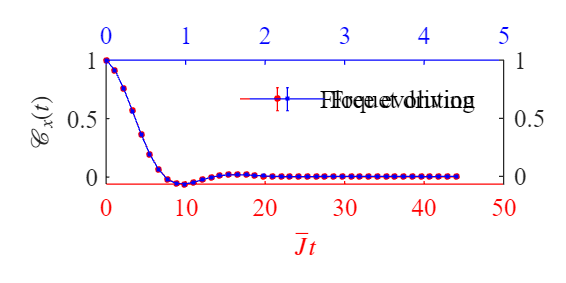


figure()
color={'#0072bd','#D95319','#eDb120','#7e2f8e','#77ac30'};
marker={'.-','-s','-s','-d'};
markersize=[8,1.5,2,2,2];

t = tiledlayout(1,1);
ax1 = axes(t);
% plot(ax1,x1,y1,marker{1},'markersize',markersize(1),'MarkerFaceColor','r','color','r','LineWidth',1)
errorbar(ax1,x1,y1,y1_uncert,marker{1},'markersize',markersize(1),'MarkerFaceColor','r','color','r','CapSize',1)
ax1.XColor = 'r';
xlabel('$\bar{J}t$','Interpreter',"latex")
ylabel('$\mathcal{C}_x(t)$','Interpreter',"latex")
legend('Floquet driving','box','off')

ax2 = axes(t);
% plot(ax2,x2,y2,marker{2},'markersize',markersize(2),'MarkerFaceColor','b','color','b')
errorbar(ax2,x2,y2,y2_uncert,marker{2},'markersize',markersize(2),'MarkerFaceColor','b','color','b','CapSize',1)
ax2.XAxisLocation = 'top';
ax2.YAxisLocation = 'right';
ax2.Color = 'none';
ax2.XColor = 'b';

ax1.Box = 'off';
ax2.Box = 'off';
legend('Free evolution','box','off')

fontname(gcf,"Times New Roman")
fontsize(gcf,10,'points')
set(gcf,'unit','centimeters','position',[10,10,8,4]);